# Nathaniel Valla 

format long
clc
clear

1. Fourier series: Calculate the Fourier series for the following functions using n = 8,16,32 and 64 interpolation points on the interval 0 ≤ x ≤ 2π, and for the n = 64 case, plot the resulting sine and cosine mode coefficients for sin(kx) and cos(kx) vs. K: 

n_8  = 2*pi*linspace(0,1,8);
n_16 = 2*pi*linspace(0,1,16);
n_32 = 2*pi*linspace(0,1,32);
n_64 = 2*pi*linspace(0,1,64);
n = 2*pi*linspace(0,1,10000);

(a) f(x) = ln(2+sinx) 

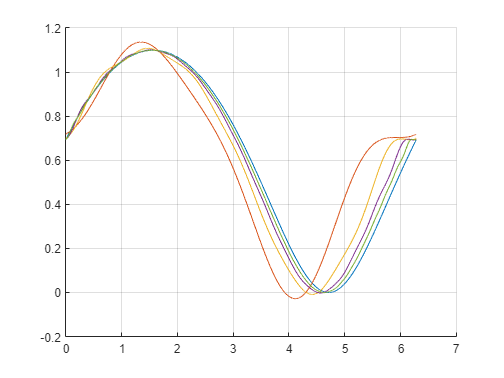

f_8  = log(2+sin(n_8));
f_16 = log(2+sin(n_16));
f_32 = log(2+sin(n_32));
f_64 = log(2+sin(n_64));
f = log(2+sin(n));

F_8  = fft(f_8);
F_16 = fft(f_16);
F_32 = fft(f_32);
F_64 = fft(f_64);

 
figure 
hold on 
plot(n,f)
plot(n,i_fft(F_8,n))
plot(n,i_fft(F_16,n))
plot(n,i_fft(F_32,n))
plot(n,i_fft(F_64,n))
grid on 
hold off

(b) f(x) = ( x ; 0 ≤ x < π 2π−x ; π < x ≤ 2π

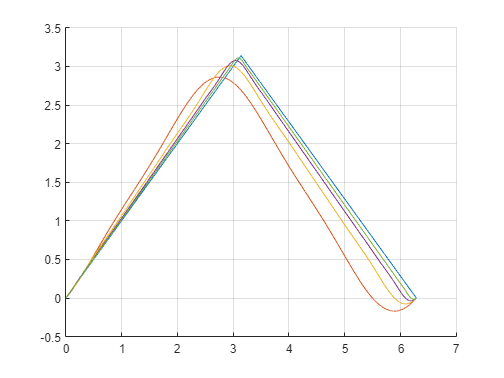

f_8  = [n_8(1:4),2*pi - n_8(5:8)];
f_16 = [n_16(1:8),2*pi - n_16(9:16)];
f_32 = [n_32(1:16),2*pi - n_32(17:32)];
f_64 = [n_64(1:32),2*pi - n_64(33:64)];
f = [n(1:5000),2*pi - n(5001:10000)];

F_8  = fft(f_8);
F_16 = fft(f_16);
F_32 = fft(f_32);
F_64 = fft(f_64);


 
figure 
hold on 
plot(n,f)
plot(n,i_fft(F_8,n))
plot(n,i_fft(F_16,n))
plot(n,i_fft(F_32,n))
plot(n,i_fft(F_64,n))
grid on 
hold off

(c) f(x) = x^2*(x−2π)^2

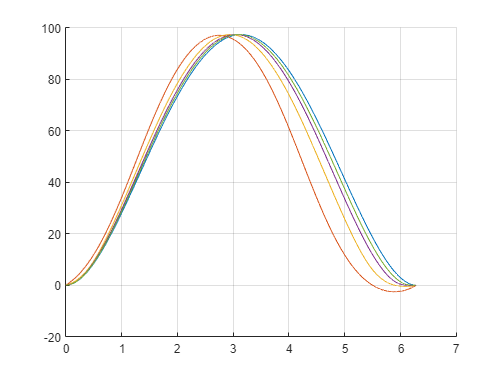

f_8  = (n_8).^2.*(n_8-2*pi).^2.;
f_16 = (n_16).^2.*(n_16-2*pi).^2.;
f_32 = (n_32).^2.*(n_32-2*pi).^2.;
f_64 = (n_64).^2.*(n_64-2*pi).^2.;
f = (n).^2.*(n-2*pi).^2;

F_8  = fft(f_8);
F_16 = fft(f_16);
F_32 = fft(f_32);
F_64 = fft(f_64);

figure 
hold on 
plot(n,f)
plot(n,i_fft(F_8,n))
plot(n,i_fft(F_16,n))
plot(n,i_fft(F_32,n))
plot(n,i_fft(F_64,n))
grid on 
hold off 

2. Numerical Differentiation:

 (a) Use the three-point centered difference formula for the second derivative to approximate f ′′(1), where f(x) = 1/x , for h = 0.1,0.01, and 0.001. Find the approximation error and verify the error estimate predicted by theory (what does the theory say?).

h_1   = 0.1;
h_01  = 0.01;
h_001 = 0.001;
 
f = @(x) 1 / x;
p = 1;

f_1   = (f(1+h_1) -2*f(1) + f(1-h_1))/h_1^2 

f_1 =    2.020202020202033


f_01  = (f(1+h_01) - 2*f(1) + f(1-h_01))/h_01^2 

f_01 =    2.000200020002563


f_001 = (f(1+h_001) - 2*f(1) + f(1-h_001))/h_001^2 

f_001 =    2.000002000235312


 (b) Develop a first-order method for approximating f ′′(x) that uses the data f(x−h), f(x), and f(x+3h) only. Find the error term. 


$$f(x-1h) = f(x) -1hf'(x)+\frac{1h^2}{2}f''(x)\\
f(x+3h) = f(x) +3hf'(x)+\frac{9h^2}{2}f''(x)\\
f(x+3h) -7f(x-1h) =  -6f(x) -4hf'(x)+\frac{h^2}{2}f''(x)\\
\frac{h^2}{2} f''(x)= f(x+3h) -7f(x-1h)+6f(x)+4hf'(x)\\
f''(x)=\frac{2(x+3h) -14f(x-1h)+12f(x)}{h^2}+\frac{8}{h}f'(x) $$


3. Riemann Sums: In each of the following problems, a function and interval of definition are given. Also a partition of the interval is specified, as well as a point in each of the sub-intervals that the partition determines. In each case, sketch the graph of f and the rectangles that this information provides and compute the Riemann sum. 

(a) f(x) = 25−x^2 , [0,5], {0,2,3,4,5}, use right endpoint 

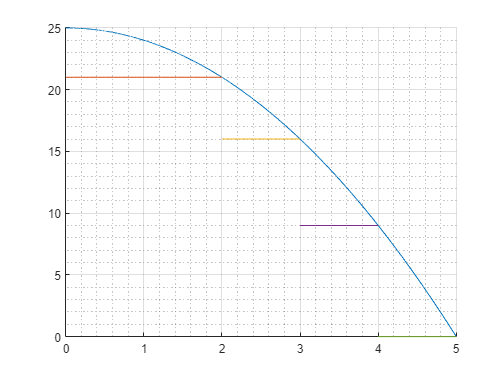

ans =     46


t = linspace(0,5,10000);
fun = @(x) 25-x.^2;
points = [0,2,3,4,5];
test = "rig";
Riemann_Sum(fun,points,test,t)

(b) f(x) = 16−x^2 , [0,4], {0,1,2,3,4}, use midpoint 

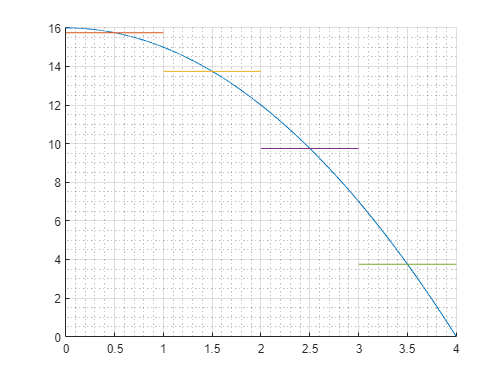

ans =     43


t = linspace(0,4,10000);
fun = @(x) 16-x.^2;
points = [0,1,2,3,4];
test = "mid";
Riemann_Sum(fun,points,test,t)

(c) f(x) = x^3 + 2, [−1,2], {−1,−0.5,0,0.5,1,1.5,2}, use left endpoint 

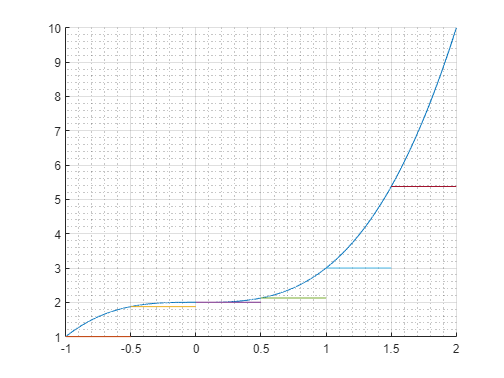

ans =   15.375000000000000


t = linspace(-1,2,10000);
fun = @(x) x.^3 + 2;
points = [-1,-0.5,0,0.5,1,1.5,2];
test = "lef";
Riemann_Sum(fun,points,test,t)

(d) f(x) = 1/x+1 , [0,2], {0,0.5,1,1.5,2}, use midpoint

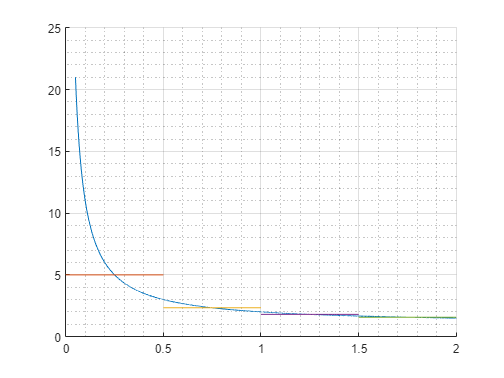

ans =   10.704761904761904


t = linspace(0.05,2,10000);
fun = @(x) 1./x + 1;
points = [0,0.5,1,1.5,2];
test = "mid";
Riemann_Sum(fun,points,test,t)

function series = i_fft(fou_ser,n)
    yy = zeros(1,size(n,2));
    L = size(fou_ser,2);
    yy = yy + real(fou_ser(1))/L*cos(0*n)- imag(fou_ser(1))/L*sin(0*n);
    for k = 2:L/2  % k is the array index
        yy = yy + 2*real(fou_ser(k))/L*cos((k-1)*n) - 2*imag(fou_ser(k))/L*sin((k-1)*n);
    end
    series = yy;
end 

function acum = Riemann_Sum(fun,points,test,t)
    apprx = zeros(1,size(points,2)-1);
    figure 
    hold on 
    grid on 
    grid minor
    plot(t,fun(t))

    if (test == "rig")
        for i = 2:size(points,2)
            apprx(i-1)= fun(points(i));
        end
    else
        if (test == "lef")
             for i = 1:(size(points,2)-1)
                 apprx(i)= fun(points(i));
             end
        else
             if (test == "mid")
                for i = 1:(size(points,2)-1)
                     apprx(i)= fun((points(i)+points(i+1))/2);
                end
             else
                fprintf("Not Valid Test method")
             end 
        end 
    end

    for i = 1:(size(points,2)-1)
         plot([points(i),points(i+1)],[apprx(i),apprx(i)])
    end
    acum = sum(apprx);
    hold off
end